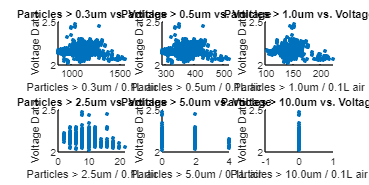

% Open a file called data.txt
fileID = fopen('data.txt', 'r');

% Read each line into a N*7 matrix, where N is the amount of lines - the amount of lines that start with #
data = textscan(fileID, '%f %f %f %f %f %f %f', 'CommentStyle', '#');
data = cell2mat(data); % Convert cell array to a numeric matrix

% Column 1: Particles > 0.3um / 0.1L air
particles_0_3um = data(:, 1);

% Column 2: Particles > 0.5um / 0.1L air
particles_0_5um = data(:, 2);

% Column 3: Particles > 1.0um / 0.1L air
particles_1_0um = data(:, 3);

% Column 4: Particles > 2.5um / 0.1L air
particles_2_5um = data(:, 4);

% Column 5: Particles > 5.0um / 0.1L air
particles_5_0um = data(:, 5);

% Column 6: Particles > 10.0um / 0.1L air
particles_10_0um = data(:, 6);

% Column 7: Voltage data from the MEMS microphone
voltage_data = data(:, 7);

% Create a figure to hold the subplots
figure;

% Array of particle sizes for titles
particleSizes = ["0.3um", "0.5um", "1.0um", "2.5um", "5.0um", "10.0um"];

% Loop through each particle size and plot against voltage data
for i = 1:6
    subplot(2, 3, i); % Arrange plots in 2 rows and 3 columns
    scatter(data(:, i), voltage_data, 'filled', 'SizeData', 10); % Adjust dot size here
    xlabel(sprintf('Particles > %s / 0.1L air', particleSizes(i)));
    ylabel('Voltage Data');
    title(sprintf('Particles > %s vs. Voltage', particleSizes(i)));
end

set(gcf, 'Position', [100, 100, 1200, 600]); % Resize figure to make it wider



for i = 1:6
    [R, P] = corrcoef(data(:, i), voltage_data);
    fprintf('Particle size > %s um: Correlation coefficient = %f, p-value = %f\n', particleSizes(i), R(1,2), P(1,2));
end

Particle size > 0.3um um: Correlation coefficient = -0.066370, p-value = 0.060604
Particle size > 0.5um um: Correlation coefficient = -0.066370, p-value = 0.060604
Particle size > 1.0um um: Correlation coefficient = -0.026366, p-value = 0.456456
Particle size > 2.5um um: Correlation coefficient = -0.202067, p-value = 0.000000
Particle size > 5.0um um: Correlation coefficient = -0.101214, p-value = 0.004162
Particle size > 10.0um um: Correlation coefficient = NaN, p-value = NaN



for i = 1:6
    lm = fitlm(voltage_data, data(:, i));
    disp(['Linear regression for particle size > ', particleSizes(i), ' um:']);
    disp(lm);
end

    "Linear regression for particle size > "    "0.3um"    " um:"



Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     1404.2     147.62     9.512    2.1443e-20
    x1             -127.43     67.815    -1.879      0.060604


Number of observations: 800, Error degrees of freedom: 798
Root Mean Squared Error: 118
R-squared: 0.00441,  Adjusted R-Squared: 0.00316
F-statistic vs. constant model: 3.53, p-value = 0.0606


    "Linear regression for particle size > "    "0.5um"    " um:"



Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     468.07     49.208     9.512    2.1443e-20
    x1             -42.476     22.605    -1.879      0.060604


Number of observations: 800, Error degrees of freedom: 798
Root Mean Squared Error: 39.4
R-squared: 0.00441,  Adjusted R-Squared: 0.00316
F-statistic vs. constant model: 3.53, p-value = 0.0606


    "Linear regression for particle size > "    "1.0um"    " um:"



Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)     164.37     25.119      6.5437    1.0724e-10
    x1             -8.5972     11.539    -0.74506       0.45646


Number of observations: 800, Error degrees of freedom: 798
Root Mean Squared Error: 20.1
R-squared: 0.000695,  Adjusted R-Squared: -0.000557
F-statistic vs. constant model: 0.555, p-value = 0.456


    "Linear regression for particle size > "    "2.5um"    " um:"



Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)      34.88     4.5125     7.7296     3.244e-14
    x1             -12.082      2.073    -5.8284    8.1194e-09


Number of observations: 800, Error degrees of freedom: 798
Root Mean Squared Error: 3.61
R-squared: 0.0408,  Adjusted R-Squared: 0.0396
F-statistic vs. constant model: 34, p-value = 8.12e-09


    "Linear regression for particle size > "    "5.0um"    " um:"



Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)     5.1287     1.4555     3.5238    0.00044963
    x1             -1.9215     0.6686    -2.8739     0.0041615


Number of observations: 800, Error degrees of freedom: 798
Root Mean Squared Error: 1.16
R-squared: 0.0102,  Adjusted R-Squared: 0.009
F-statistic vs. constant model: 8.26, p-value = 0.00416


    "Linear regression for particle size > "    "10.0um"    " um:"



Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate    SE    tStat    pValue
                   ________    __    _____    ______

    (Intercept)       0        0      NaN      NaN  
    x1                0        0      NaN      NaN  


Number of observations: 800, Error degrees of freedom: 798
R-squared: NaN,  Adjusted R-Squared: NaN
F-statistic vs. constant model: NaN, p-value = NaN
